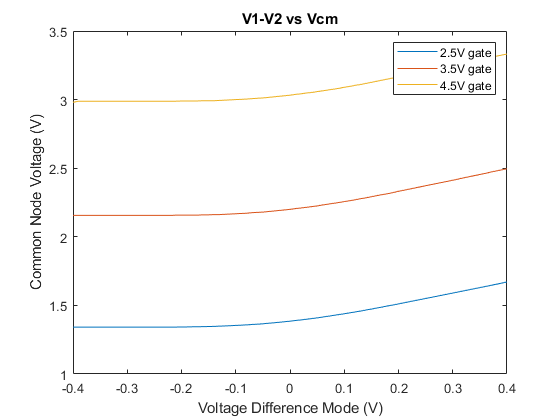

%plot 2 lab 5

% Also include a plot showing the common-source node voltage, V , as a function of
% V1 − V2 for all three values of V2.

load('0.7V_bias_below_threshold\2.5V gate\Source\Vgate.mat')
load('0.7V_bias_below_threshold\2.5V gate\Source\Vsource.mat')

V1_minus_V2_2V = Vgate; 
Vcm_2V = Vsource; 

load('0.7V_bias_below_threshold\3.5V gate\Source\Vgate.mat')
load('0.7V_bias_below_threshold\3.5V gate\Source\Vsource.mat')

V1_minus_V2_3V = Vgate; 
Vcm_3V = Vsource; 

load('0.7V_bias_below_threshold\4.5V gate\Source\Vgate.mat')
load('0.7V_bias_below_threshold\4.5V gate\Source\Vsource.mat')

V1_minus_V2_4V = Vgate; 
Vcm_4V = Vsource;


plot(V1_minus_V2_2V, Vcm_2V)
hold on 
plot(V1_minus_V2_3V, Vcm_3V)
hold on 
plot(V1_minus_V2_4V, Vcm_4V)
title("V1-V2 vs Vcm")
xlabel("Voltage Difference Mode (V)")
ylabel("Common Node Voltage (V)")
legend("2.5V gate", "3.5V gate", "4.5V gate")